clear
load(['\\dartfs-hpc.dartmouth.edu\rc\lab\R\RimbergA\cCPT_NR_project\Bhar_measurements\2021_October_Jules_sample\' ...
    '11-3-21_freq_ramp_hist_vna_deformed\run_1\data\corrected_complete_run_data.mat'])
load(['\\dartfs-hpc.dartmouth.edu\rc\lab\R\RimbergA\cCPT_NR_project\Bhar_measurements\2021_October_Jules_sample\' ...
    '11-3-21_freq_ramp_hist_vna_deformed\run_1\data\run_number_1_VNA_data_-47dBm.mat'], ...
    'data_real_with_flucs', 'data_imag_with_flucs', 'xdata_1_before_m65', 'subtracted_log_mag', 'subtracted_phase', ...
    'res_freq_fit_angle');
res_freq_high_power = res_freq_fit_angle;
load(['\\dartfs-hpc.dartmouth.edu\rc\lab\R\RimbergA\cCPT_NR_project\Bhar_measurements\2021_October_Jules_sample\' ...
    '11-3-21_freq_ramp_hist_vna_deformed\run_1\data\run_number_1_VNA_data_-65dBm.mat'], 'res_freq_fit_angle');
%%%%% detuning array is loaded in MHz %%%%%

Approximating sigmoid function as 

$P(\Delta) = \frac{1}{1 + e^{-\frac{(\Delta - \Delta_0)}{\gamma}}$  where $\gamma$ is the rate at which it goes from prob = 0 to prob = 1 and $\Delta_0$ is the point at which it is exactly halfway switched.

% probability_best_180_360(probability_best_180_360 < 0.08) = 0; 
% probability_best_180_360(probability_best_180_360 > 0.92) = 1;
gamma_MHz = 1; 
delta_0 = -1.1;
sigmoid_prob = 1./(1 + exp(-(detuning_array - delta_0)./gamma_MHz));
error_by_hand_sigmoid = mean((probability_best_180_360 - sigmoid_prob).^2);
%%% fit only values between 0.1 and 0.9, since it tends to saturate at 0.1
%%% and a little above 0.9
% [sigmoid_fit_params, sigmoid_fit_values, sigmoid_fit_error] = ...
%     fit_sigmoid(detuning_array(probability_best_180_360<0.91 & probability_best_180_360 > 0.1), ...
%     probability_best_180_360(probability_best_180_360<0.91 & probability_best_180_360 > 0.1));

%%%%%
[sigmoid_fit_params, sigmoid_fit_values, sigmoid_fit_error] = ...
    fit_sigmoid(detuning_array, probability_best_180_360);
error_by_hand_sigmoid

error_by_hand_sigmoid = 0.0034

sigmoid_fit_error

sigmoid_fit_error = 0.0025

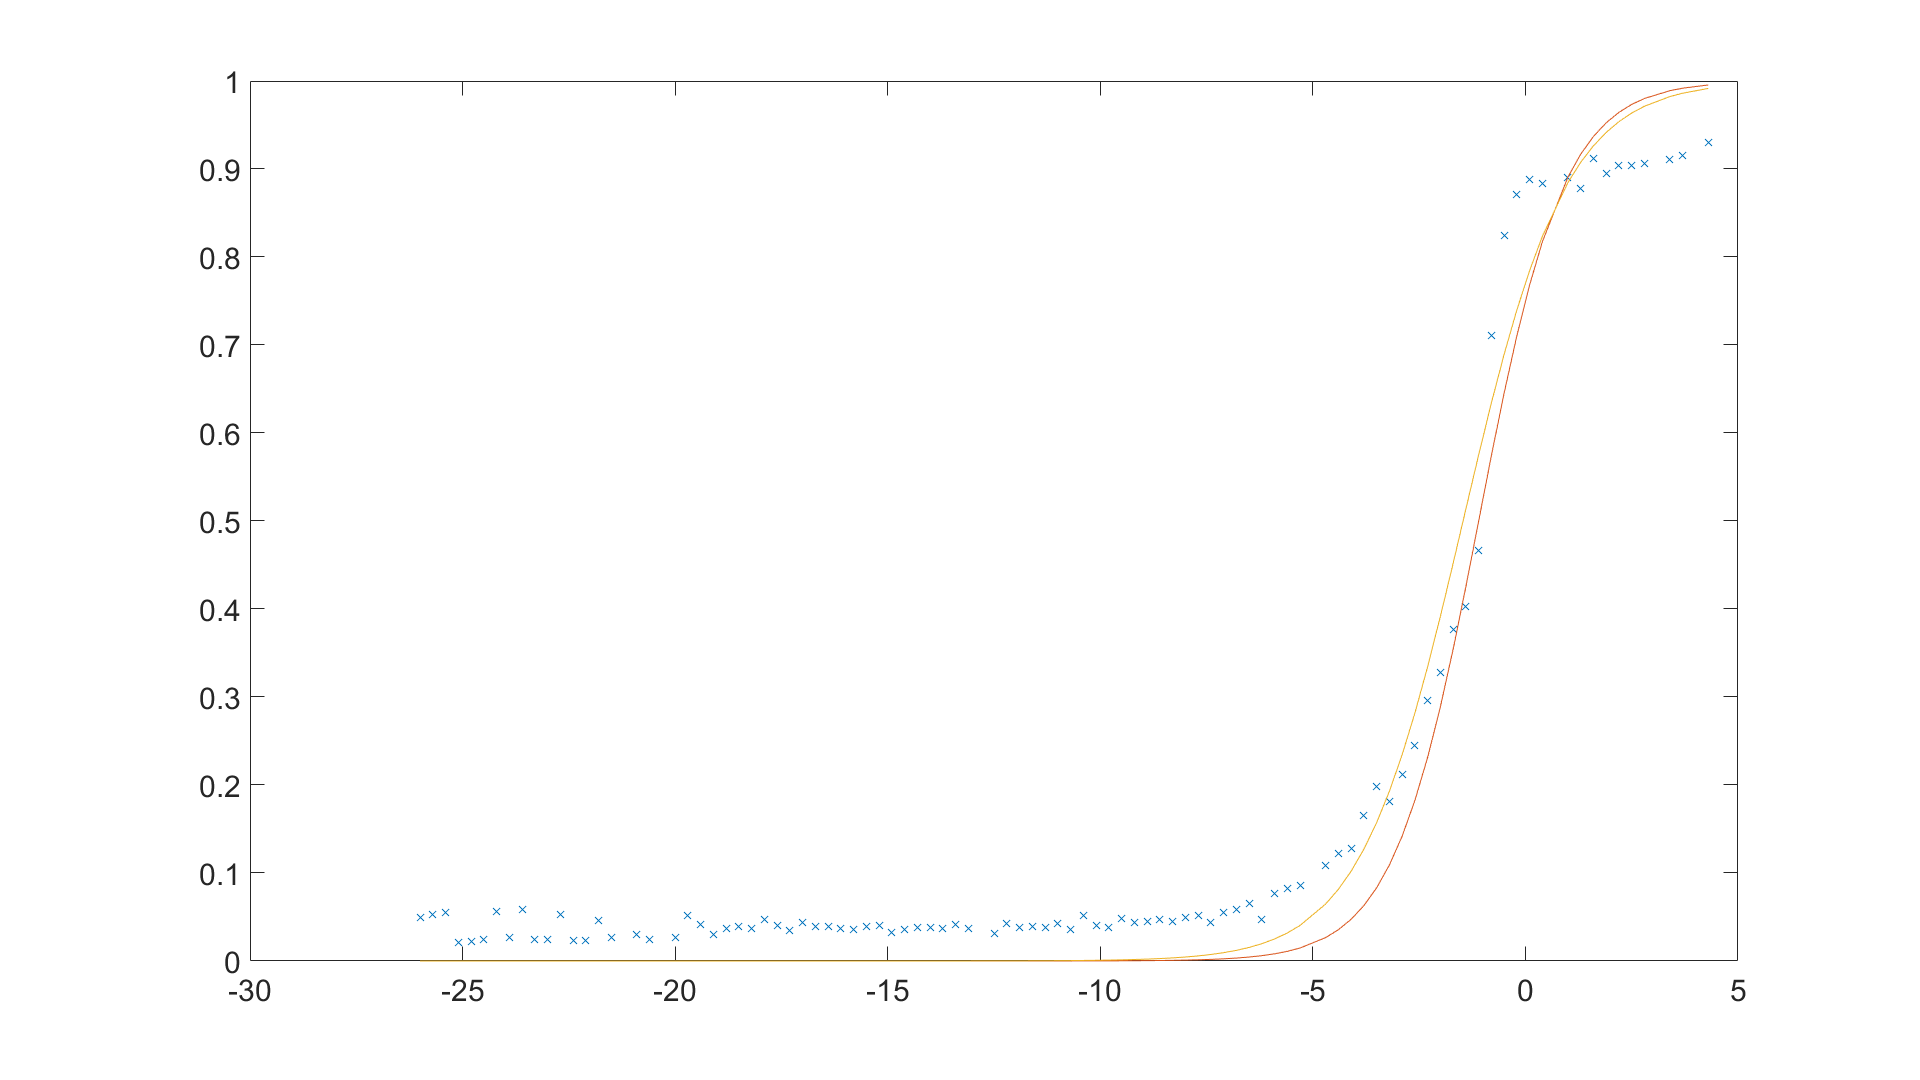

figure
plot(detuning_array, probability_best_180_360, 'x', 'displayName', 'data')
hold on
plot(detuning_array, sigmoid_prob)
% plot(detuning_array(probability_best_180_360<0.91 & probability_best_180_360 > 0.1), sigmoid_fit_values)
plot(detuning_array, sigmoid_fit_values)